clear

img = imread('../images/cavendish.jpg');
[Ny, Nx, Ncolours] = size(img)

Ny = 600

Nx = 800

Ncolours = 3

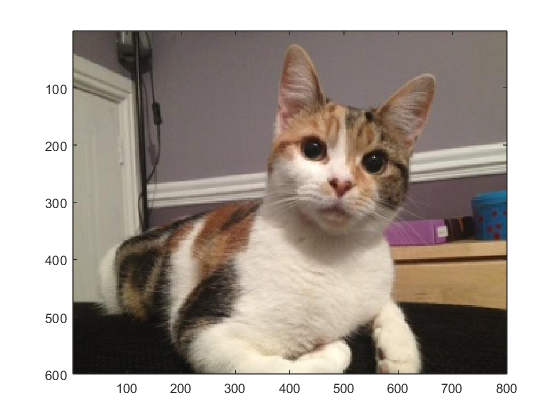

image(img)
exportgraphics(gcf,'cavendish_plot.png','Resolution',300) 

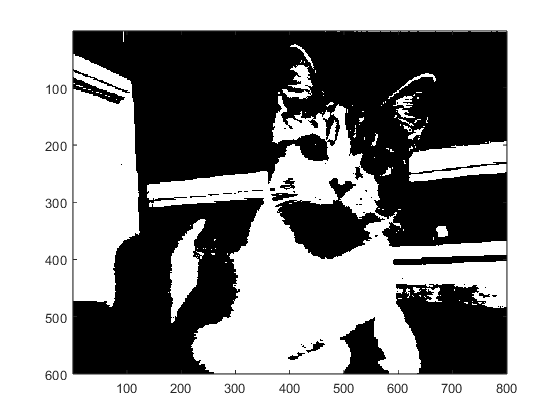

figure()

% Get size of image array
[Ny, Nx, Ncolours] = size(img);

% Reshape image array
img_bw = reshape(img, [Nx * Ny, Ncolours]);

% Calculate average colour of each pixel
avg = mean(img_bw, 2);

% Change each pixel to black or white depending on the average colour
img_bw(avg <= 128, :) = 0;
img_bw(avg > 128, :) = 255;

% Reshape image array back to the original shape
img_bw = reshape(img_bw, [Ny, Nx, Ncolours]);

% Plot image array
image(img_bw)
exportgraphics(gcf,'cavendish_bw.png','Resolution',300) 